### 1.Load the Dataset 

% Read the data
data = readtable('diabetes.csv');

% Display the first 5 rows
disp(data(1:5, :))

    Pregnancies    Glucose    BloodPressure    SkinThickness    Insulin    BMI     DiabetesPedigreeFunction    Age    Outcome
    ___________    _______    _____________    _____________    _______    ____    ________________________    ___    _______

         6           148           72               35              0      33.6             0.627              50        1   
         1            85           66               29              0      26.6             0.351              31        0   
         8           183           64                0              0      23.3             0.672              32        1   
         1            89           66               23         

### 2.Define Features and Target

x=data(:,1:end-1);
y=data.Outcome;

### 3.Stratified Train-Test Split

rng(13);% ensures the split is reproducible.
cv = cvpartition(y, 'HoldOut', 0.3, 'Stratify', true); %keeps class balance in train and test sets.
x_train=x(training(cv),:);
y_train=y(training(cv));
x_test=x(test(cv),:);
y_test=y(test(cv));

### 4.Train the Naive Bayes Classifier

nb_model=fitcnb(x_train,y_train);%Fits a Naive Bayes classifier using training data.

% 5. Predict on the Test Set
[y_pred, posterior] = predict(nb_model, x_test);
% y_pred: predicted classes (0 or 1) for the test data.
% posterior: probabilities for each class — [P(No Diabetes), P(Diabetes)] for each test instance.

% 6. Evaluate Performance
confmat = confusionmat(y_test, y_pred);
disp('Confusion Matrix:');

Confusion Matrix:


disp(confmat);

   129    21
    27    53




accuracy = sum(diag(confmat)) / sum(confmat(:));
disp(['Accuracy: ', num2str(accuracy)]);

Accuracy: 0.7913



% 7. Predict for a Single Instance
sample_instance = x_test(1, :);
[predicted_class, predicted_prob] = predict(nb_model, sample_instance);

disp('Prediction for First Test Instance:');

Prediction for First Test Instance:


disp(['Predicted Class: ', num2str(predicted_class)]);

Predicted Class: 0


disp(['Probability (No Diabetes): ', num2str(predicted_prob(1))]);

Probability (No Diabetes): 0.93568


disp(['Probability (Diabetes): ', num2str(predicted_prob(2))]);

Probability (Diabetes): 0.064318



% 8. Predict and Display Results for First 30 Test Instances
num_to_display = min(30, size(x_test,1));  % Handle cases with fewer than 30 test samples
T = table(y_test(1:num_to_display), y_pred(1:num_to_display), ...
    posterior(1:num_to_display,1), posterior(1:num_to_display,2), ...
    'VariableNames', {'TrueLabel', 'PredictedLabel', 'P_NoDiabetes', 'P_Diabetes'});

disp('Full Prediction Results for First 30 Test Instances:');

Full Prediction Results for First 30 Test Instances:


disp(T);

    TrueLabel    PredictedLabel    P_NoDiabetes    P_Diabetes
    _________    ______________    ____________    __________

        0              0              0.93568       0.064318 
        1              0              0.97014       0.029857 
        0              1              0.19787        0.80213 
        1              0              0.54923        0.45077 
        1              1              0.42559        0.57441 
        1              0              0.88885        0.11115 
        0              0              0.63421        0.36579 
        1              1             0.057285        0.94271 
        0              0               0.6852         0.3148 
        0              0              0.96681       0.033194 
        1              0              0.91496       0.085038 
        1              1              0.12141        0.87

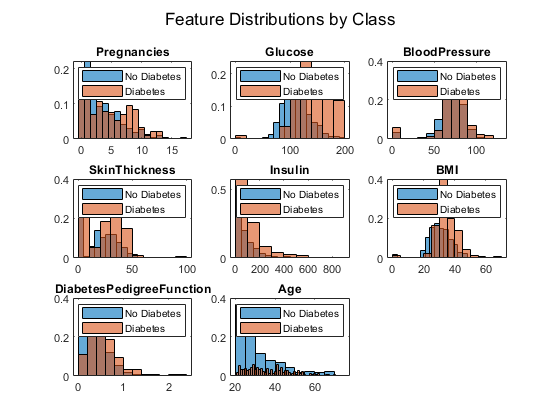

% 9. Visualize Feature Distributions
% Ensure proper array conversion 
feature_names = x.Properties.VariableNames;
if istable(x_train)
    X_train = table2array(x_train);
else
    X_train = x_train;
end
if istable(y_train)
    y_train = table2array(y_train);
end

num_features = length(feature_names);
mu = nb_model.DistributionParameters(:, 1);
sigma = nb_model.DistributionParameters(:, 2);

figure;
for i = 1:num_features
    subplot(3, 3, i);
    histogram(X_train(y_train == 0, i), 'Normalization', 'probability');
    hold on;
    histogram(X_train(y_train == 1, i), 'Normalization', 'probability');
    title(feature_names{i});
    legend('No Diabetes', 'Diabetes');
end
sgtitle('Feature Distributions by Class');

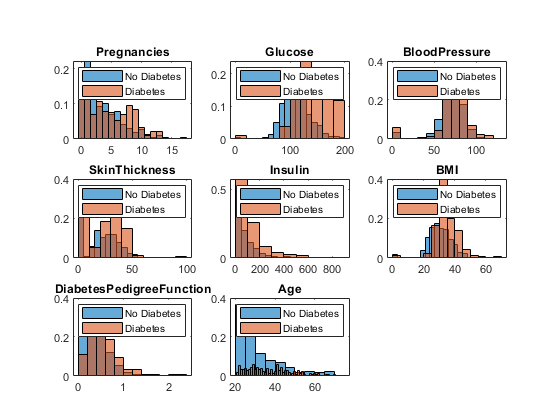

saveas(gcf, 'variables.png')